  
clc; clear; close all;

## PYTHON LIBRARY LOAD

try
    fabio = py.importlib.import_module('fabio');
    detectors = py.importlib.import_module('pyFAI.detectors');
    azimuthal = py.importlib.import_module('pyFAI.azimuthalIntegrator');
    disp('Python libraries loaded.');
catch
    error('파이썬 라이브러리 로드 실패. pyFAI/fabio 설치 확인 필요.');
end

Python libraries loaded.


## DATA PATH SETTING

folder = "Z:\KEK_2512_h5\results\KEK_2512";
SampleList=folder_list(folder);
sample = SampleList(2);
path = sprintf('%s/%s',folder,sample);
RunList=folder_list(path);
runname =  RunList(1);
td_path = "/delayinfo/delay";
h5_path = sprintf("%s/%s/raw/images/image_pairs.h5",path,runname);
td_str = h5read(h5_path,td_path);
td = td_str(6);

## DATA LOAD

h5 for one time delay, poni and mask

Data = struct;
[Data.on, Data.off] = KEK_h5_load(h5_path,td);
poni = "C:\Users\user\Desktop\MNGN\DnCNN\Detector_poni.poni";
mask = read_mask("C:\Users\user\Desktop\Si_mask.edf"); % need read_mask function file

## AI SETTING

unit, polarization factor, num_q and mask

ai = AI(poni,detectors,azimuthal);
num_q = 1024;
ai_option = pyargs('unit', 'q_A^-1','polarization_factor', 0.99,'mask', mask);

## AI START

get azimuthal integrated on and off data + q list ai_start

Data = ai_start(ai,Data,ai_option,num_q); % make Data.q, Data.ai.on and Data.ai.off

## AUC NORMALIZATION

get auc normalized on and off data for given range

norm_range = [4 6];
Data = auc_norm(Data,norm_range);

## AUC CUT

get good img

cut_range = [2 6];
Data = auc_cut(Data,cut_range);

cut range: 0 ~ 0.0024233


## FIGURE

plot $\Delta S\left(q\right)$ for selected run and time delay

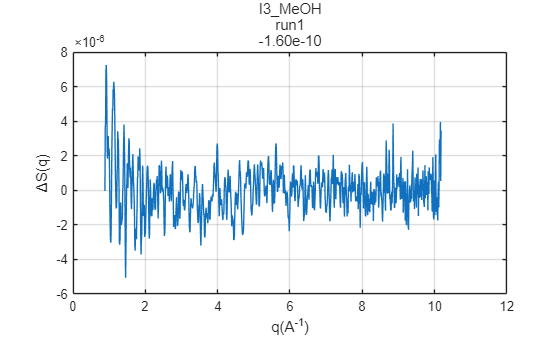

figure;
plot(Data.q,Data.mean);
title([sample runname td],Interpreter="none");
xlabel('q(A^{-1})');
ylabel('\DeltaS(q)');
grid on;

## FUNCTIONS

- `folder_list(foldername)` returns subfolder list of the given foldername.

function lst = folder_list(foldername)
    arguments
        foldername (1,1) string {mustBeFolder}
    end
    d = dir(foldername);
    lst = string({d([d.isdir]&~ismember({d.name},{'.','..'})).name})';
end

- `KEK_h5_load(filename,td)` returns on and off img datasets of **h5** at time delay with td.

function [on, off] = KEK_h5_load(filename,td)
    arguments
        filename (1,1) string {mustBeFile} 
        td (1,1) string
    end
    if ~endsWith(filename, ".h5", 'IgnoreCase', true)
        error("filename must be **.h5** format!");
    end
    path_on  = sprintf("/delays/delay_%s/on" ,td);
    path_off = sprintf("/delays/delay_%s/off",td);
    
    on  = h5read(filename,path_on );
    off = h5read(filename,path_off);
    
    on  = double(permute(on,  [1 3 2]));
    off = double(permute(off, [1 3 2]));
end

- `AI(poni_path,detectors,azimuthal)` returns `azimuthal.AzimuthalIntegrator` with given parameters.

function ai = AI(poni_path,detectors,azimuthal)
    arguments
        poni_path (1,1) string {mustBeFile}
        detectors (1,1) py.module
        azimuthal (1,1) py.module

    end

    poni = read_poni(poni_path); % need read_poni function file
    
    pixel_size1 = poni.PixelSize1;
    pixel_size2 = poni.PixelSize2;
    dist        = poni.Distance;
    poni1       = poni.Poni1;
    poni2       = poni.Poni2;
    rot1        = poni.Rot1;
    rot2        = poni.Rot2;
    rot3        = poni.Rot3;
    wavelength  = poni.Wavelength;
    
    det_shape = py.tuple({int32(2048), int32(2048)});
    detector = detectors.Detector(pixel_size1, pixel_size2, pyargs('max_shape', det_shape));
    
    ai_params = pyargs(...
        'dist', dist, 'poni1', poni1, 'poni2', poni2, ...
        'rot1', rot1, 'rot2', rot2, 'rot3', rot3, ...
        'detector', detector, 'wavelength', wavelength);
    
    ai = azimuthal.AzimuthalIntegrator(ai_params);
end

- `ai_start(ai,Data,ai_option,num_q)` returns azimuthal integrated on and off datasets. also q vector.

`        Data.ai.on, Data.ai.off `and` Data.q`

function Data = ai_start(ai,Data,ai_option,num_q)
arguments
    ai (1,1) py.pyFAI.integrator.azimuthal.AzimuthalIntegrator
    Data (1,1) struct
    ai_option (1,1) pyargs
    num_q (1,1) double {mustBePositive} = double(1024)
end
    num_shot = size(Data.on,1);
    Data.ai.on = cell(num_shot, 1);
    Data.ai.off = cell(num_shot, 1);
    for i = 1 : num_shot
        res_on = ai.integrate1d(squeeze(Data.on(i,:,:)), int32(num_q), ai_option);
        Data.ai.on{i} = double(res_on{2}.tolist())';
    
        res_off = ai.integrate1d(squeeze(Data.off(i,:,:)), int32(num_q), ai_option);
        Data.ai.off{i} = double(res_off{2}.tolist())';
    end
    Data.q = double(res_on{1}.tolist())';
end

- `auc_norm(Data,norm_rage)` normalize the Data with norm_range and get difference of normalized datasets.

`        Data.normalized.on, Data.normalizedoff` and `Data.diff`

function Data = auc_norm(Data,norm_range)
arguments
    Data (1,1) struct
    norm_range (1,2) double {mustBePositive} = [4 6]
end
norm_idx = find(Data.q>=norm_range(1)&Data.q<=norm_range(2));
M_on  = [Data.ai.on{ :}];
M_off = [Data.ai.off{:}];

norm_factor_on  = sum(M_on( norm_idx,:),1);
norm_factor_off = sum(M_off(norm_idx,:),1);

Data.normalized.on  = M_on  ./ norm_factor_on;
Data.normalized.off = M_off ./ norm_factor_off;

Data.diff = Data.normalized.on - Data.normalized.off;
end

- `auc_cut(Data,cut_range)` user cuts bad imgs. get good $\Delta S\left(q,t_{\mathrm{given}} \right)$.

`        Data.good_DS, Data.mean`

function Data = auc_cut(Data,cut_range)
arguments
    Data (1,1) struct
    cut_range (1,2) double {mustBePositive} = [2 6]
end

cut_idx = find(Data.q>=cut_range(1)&Data.q<=cut_range(2));

abs_DS = abs(Data.diff);
A = sum(abs_DS(cut_idx,:),1);

figure;
semilogy(1:length(A),A,'o');
title('click cut threshold');
[~, y_click] = ginput(1);
close;
good_range = [0 y_click];
disp(['cut range: ', num2str(0),' ~ ',num2str(y_click)]);
good_idx = find(A>=good_range(1)&A<=good_range(2));
Data.good_DS = Data.diff(:,good_idx);
Data.mean = mean(Data.good_DS,2);
end